# Plot M3C Variables

buffer

buffer = struct with fields:
              Ts: 1.0000e-04
              is: [9×2000 double]
             ixy: [6×2000 double]
              iB: [9×2000 double]
              iz: [9×2000 double]
              ie: [4×2000 double]
              vs: [9×2000 double]
             vxy: [6×2000 double]
              vB: [9×2000 double]
              vo: [0 0.0272 0.1364 0.3063 0.4907 0.6553 0.7828 0.8690 0.9196 0.9476 0.9681 0.9929 1.0257 1.0624 1.0943 1.1127 1.1127 1.0941 1.0613 1.0223 0.9874 0.9658 0.9634 0.9800 1.0106 1.0477 1.0840 1.1145 1.1363 1.1492 1.1559 … ] (1×2000 double)
              Ec: [9×2000 double]
              vc: [9×2000 double]
         Ec_mean: [202500 2.0250e+05 2.0250e+05 2.0251e+05 2.0252e+05 2.0252e+05 2.0253e+05 2.0254e+05 2.0255e+05 2.0256e+05 2.0256e+05 2.0257e+05 2.0258e+05 2.0259e+05 2.0260e+05 2.0260e+05 2.0261e+05 2.0262e+05 2.0263e+05 2.0264e+05 … ] (1×2000 double)
    Ec_mean_filt: [202500 2.0250e+05 2.0250e+05 2.0250e+05 2.0250e+05 2.0250e+05 2.0250e+05 2.02

clf

## is

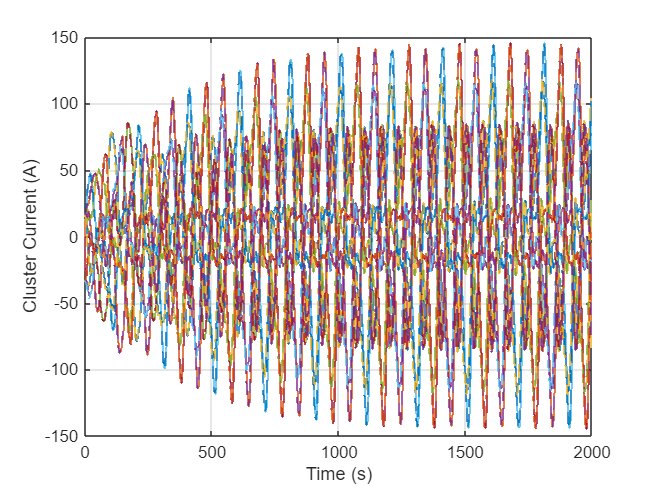

figure
stairs(buffer.is')
hold on
stairs(buffer.is_ref', '--')
hold off
xlabel('Time (s)')
ylabel('Cluster Current (A)')
grid on

## ixy

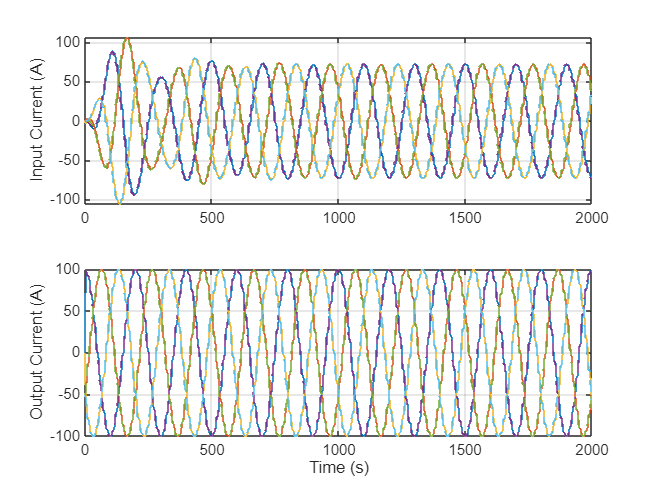

figure
subplot(2, 1, 1)
stairs(buffer.ixy(1:3, :)')
hold on
stairs(buffer.ixy_ref(1:3, :)', '--')
hold off

ylabel('Input Current (A)')
grid on

subplot(2, 1, 2)
stairs(buffer.ixy(4:6, :)')
hold on
stairs(buffer.ixy_ref(4:6, :)', '--')
hold off

xlabel('Time (s)')
ylabel('Output Current (A)')
grid on

## `iB`

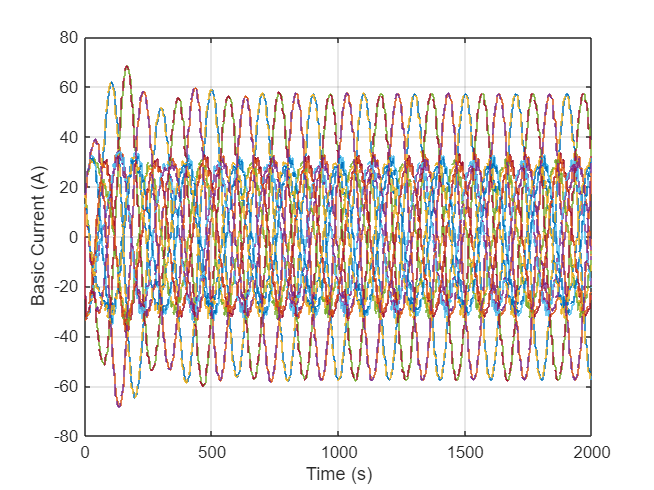

figure
stairs(buffer.iB')
hold on
stairs(buffer.iB_ref', '--')
hold off
xlabel('Time (s)')
ylabel('Basic Current (A)')
grid on

## `iz`

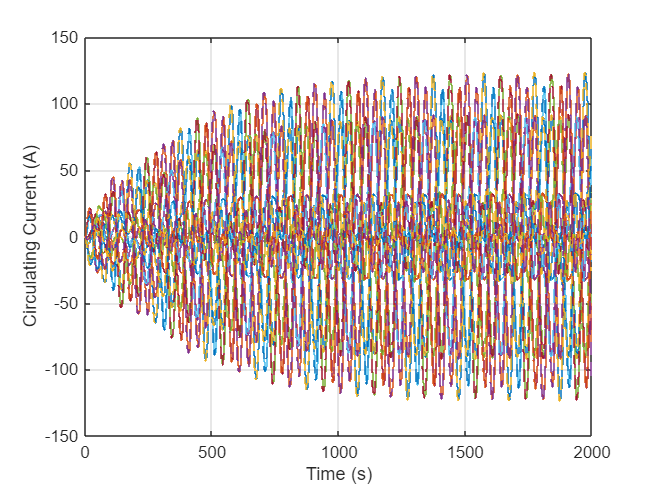

figure
stairs(buffer.iz')
hold on
stairs(buffer.iz_ref', '--')
hold off
xlabel('Time (s)')
ylabel('Circulating Current (A)')
grid on

## `ie`

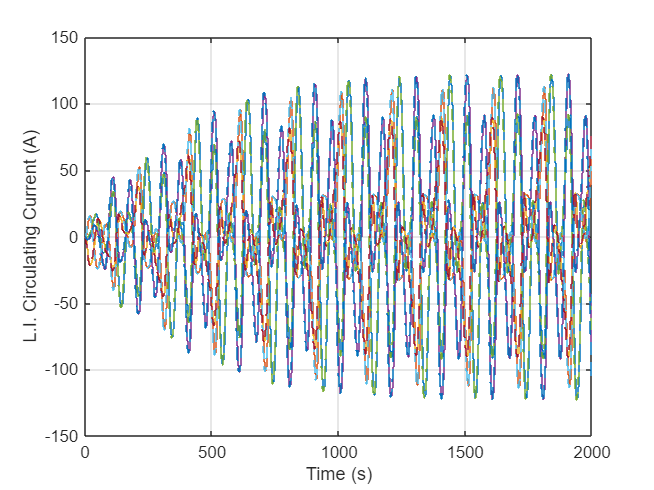

figure
stairs(buffer.ie')
hold on
stairs(buffer.ie_ref', '--')
hold off
xlabel('Time (s)')
ylabel('L.I. Circulating Current (A)')
grid on

## `vs`

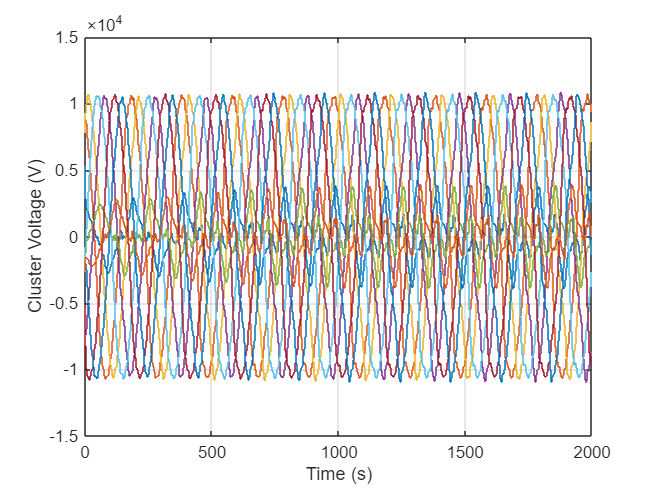

figure
stairs(buffer.vs')
xlabel('Time (s)')
ylabel('Cluster Voltage (V)')
grid on

## `vxy`

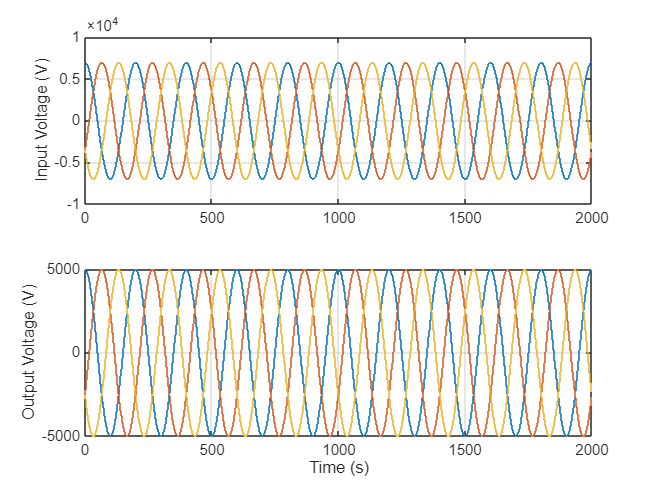

figure
subplot(2, 1, 1)
stairs(buffer.vxy(1:3, :)')

ylabel('Input Voltage (V)')
grid on

subplot(2, 1, 2)
stairs(buffer.vxy(4:6, :)')

xlabel('Time (s)')
ylabel('Output Voltage (V)')
grid on

## `vB`

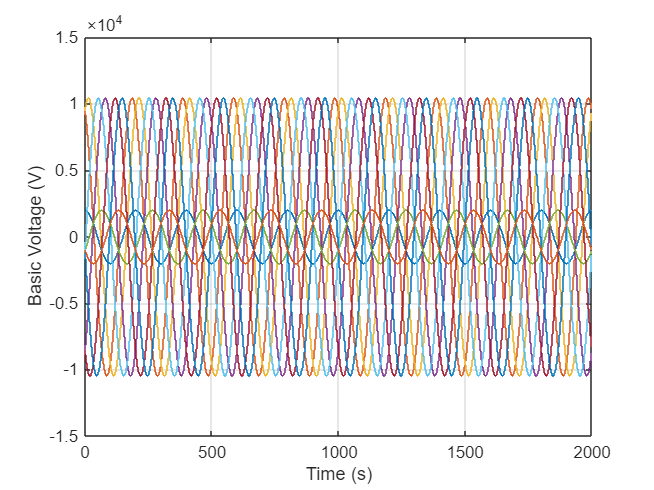

figure
stairs(buffer.vB')
xlabel('Time (s)')
ylabel('Basic Voltage (V)')
grid on

## `vo`

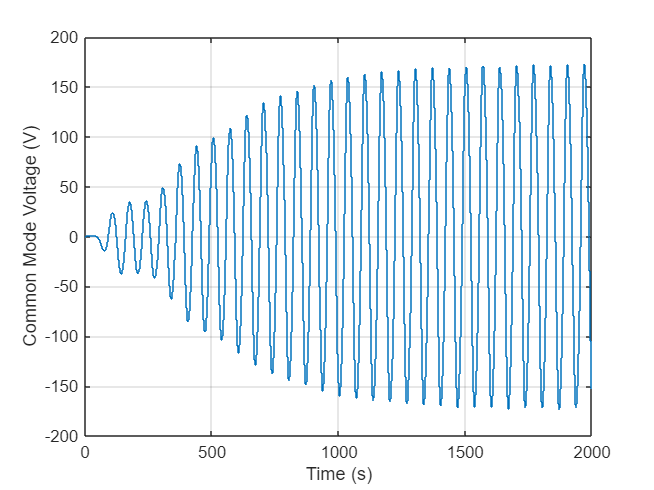

figure
stairs(buffer.vo')
xlabel('Time (s)')
ylabel('Common Mode Voltage (V)')
grid on

## `Ec`

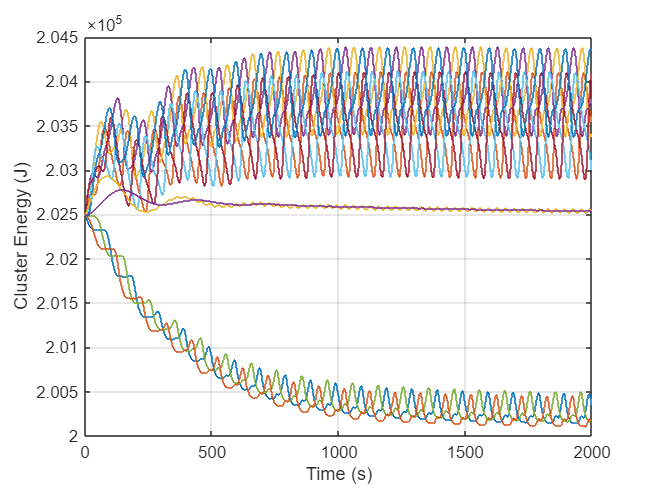

figure
stairs(buffer.Ec')
hold on
stairs(buffer.Ec_mean')
stairs(buffer.Ec_mean_filt')
hold off
xlabel('Time (s)')
ylabel('Cluster Energy (J)')
grid on

## `vc`

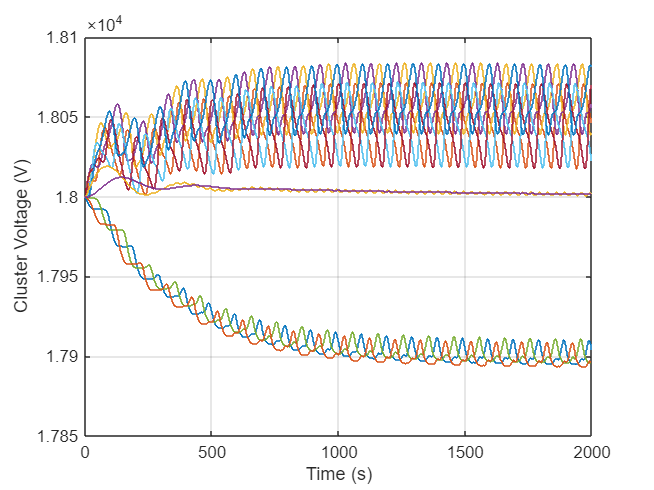

figure
stairs(buffer.vc')
hold on
stairs(buffer.vc_mean')
stairs(buffer.vc_mean_filt')
hold off
xlabel('Time (s)')
ylabel('Cluster Voltage (V)')
grid on